clear;
load('config.mat', "dirname", "block_Nx", "block_Ny");
N_beacon = 12;
beacon = 0;
% 循环读取 12 个 beacon 的数据
for i=1:N_beacon
    filename = sprintf('%s%s%d.mat', dirname, 'Beacon_sig_proc_', i);
    load(filename, 'y_smooth');
    if i == 1
        beacon = y_smooth';
    else
        beacon = [beacon; y_smooth'];
    end
end


N_tag = block_Nx * block_Ny;
tag = 0;
% 循环读取 12 个 beacon 的数据
for i=1:N_tag
    filename = sprintf('%s%s%d.mat', dirname, 'sig_proc_', i);
    load(filename, 'y_smooth');
    if i == 1
        tag = y_smooth';
    else
        tag = [tag; y_smooth'];
    end
end


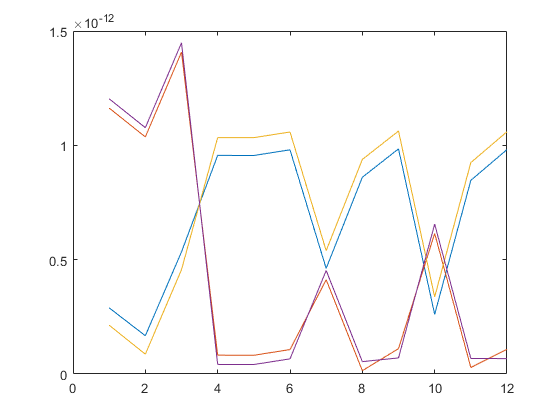

y_sig =  [beacon;tag];
D = pdist(y_sig);
D = squareform(D);
distance = D(N_beacon + 1:end, 1:N_beacon)';
figure;plot(distance);

%% 保存
filename = sprintf('%s%s.mat', dirname, 'distance');
save(filename, 'distance');
